% Generate example SISO data
x = linspace(0, 2, 100)'; % Input data x = [0 2]
y = x.^2 + 2 * sqrt(x) - 1; % 老師給的 x^2 + 2 * sqrt(x) - 1
y = y + 0.1 * randn(size(x)); % Output data with some noise

NN

% Create and train a neural network //創建並訓練神經網路
net = fitnet(10); % Create a feedforward network with 10 hidden neurons //10個隱藏神經元
net = train(net, x', y'); % Train the network

### GA

使用遺傳算法 GA 來尋找最佳解

% Define the fitness function //定義適應度函數
fitnessFunction = @(input) net(input);

% Set options for the genetic algorithm
options = optimoptions('ga', 'Display', 'iter');

% Run the genetic algorithm to find the optimal input //找最佳輸入
[optimalInput, optimalOutput] = ga(@(input) -fitnessFunction(input), 1, [], [], [], [], 0, 2, [], options);


Single objective optimization:
1 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          -5.691          -3.056        0
    2              147          -5.691          -3.613        1
    3              194          -5.691          -4.119        2
    4              241          -5.691          -4.598        3
    5              288          -5.691          -5.175        4
    6              335          -5.691          -5.347        5
    7              382          -5.691          -5.493        6
    8              429          -5.756          -5.561        0
    9              476          -5.756          -5.565        1
   10              523          -5.756          -5.688        2
   11        


% The negative sign in the fitness function is used to maximize the output,
% because GA minimizes the fitness function by default.
% //負號用於最大化輸出, 因為默認是最小化適應度函數
optimalOutput = -optimalOutput;

% Display the results //結果
fprintf('最佳輸入(GA): %.4f\n', optimalInput);

最佳輸入(GA): 2.0000


fprintf('最佳輸出(GA): %.4f\n', optimalOutput);

最佳輸出(GA): 5.8024


繪製圖形

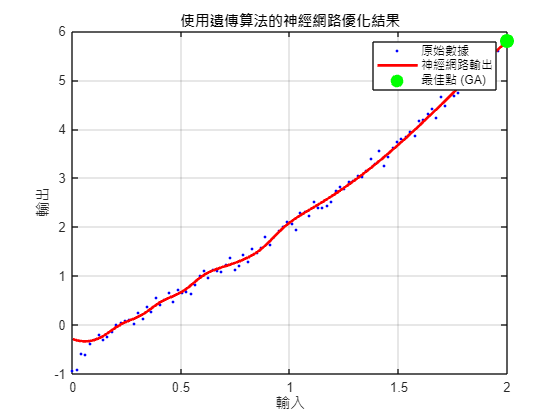

% Plot the original data //原始數據
figure;
plot(x, y, 'b.');
hold on;

% Plot the neural network output
y_pred = net(x');
plot(x, y_pred, 'r-', 'LineWidth', 2);

% Plot the optimal point found by the genetic algorithm 繪製最佳點
plot(optimalInput, optimalOutput, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
legend('原始數據', '神經網路輸出', '最佳點 (GA)');
title('使用遺傳算法的神經網路優化結果');
xlabel('輸入');
ylabel('輸出');
grid on;
hold off;

### PSO

利用 PSO 尋找最佳化值

% 定義適應度函數，對神經網路進行輸入優化
fitnessFunction = @(input) -net(input); % 使用負號來進行最大化

% 變數數量
nvars = 1; % 單變數問題（輸入）

% 定義上下界 x = [0 2]
lb = 0; % 下界 
ub = 2; % 上界

% 使用粒子群算法進行優化
[optimalInput_PSO, optimalOutput_PSO, exitflag, output] = particleswarm(fitnessFunction, nvars, lb, ub);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.



% 反轉符號以獲得實際的最大化結果
optimalOutput_PSO = -optimalOutput_PSO;

% 最佳解
fprintf('最佳輸入（PSO）：%.4f\n', optimalInput_PSO);

最佳輸入（PSO）：2.0000


fprintf('最佳輸出（PSO）：%.4f\n', optimalOutput_PSO);

最佳輸出（PSO）：5.8024


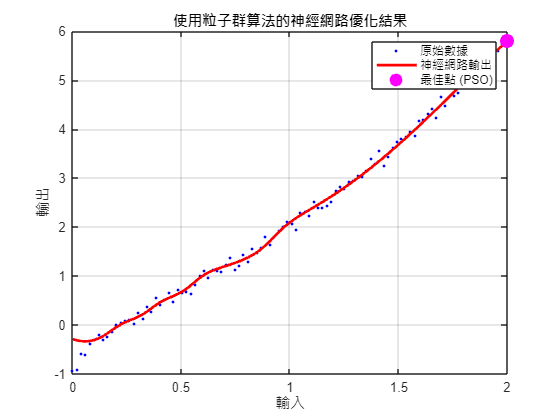


% 繪製神經網路和PSO結果
figure;
plot(x, y, 'b.');
hold on;

% 繪製神經網路輸出
y_pred = net(x');
plot(x, y_pred, 'r-', 'LineWidth', 2);

% 繪製最佳點
plot(optimalInput_PSO, optimalOutput_PSO, 'mo', 'MarkerSize', 10, 'MarkerFaceColor', 'm');
title('使用粒子群算法的神經網路優化結果');
xlabel('輸入');
ylabel('輸出');
grid on;
legend('原始數據', '神經網路輸出', '最佳點 (PSO)');
hold off;